close all; clear; clc

## Load Image

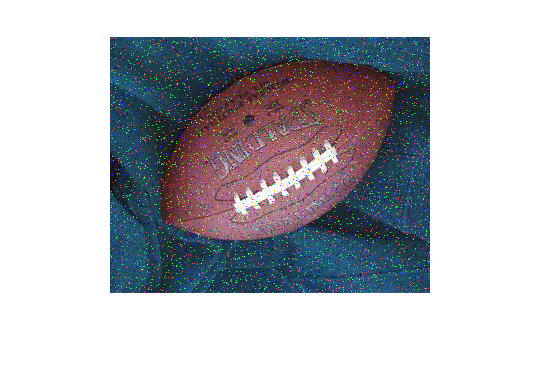

img = imread('.\Football_Noise.bmp');
rotated = uint8(rotate(img));
imshow(rotated)

## Noise Filtering

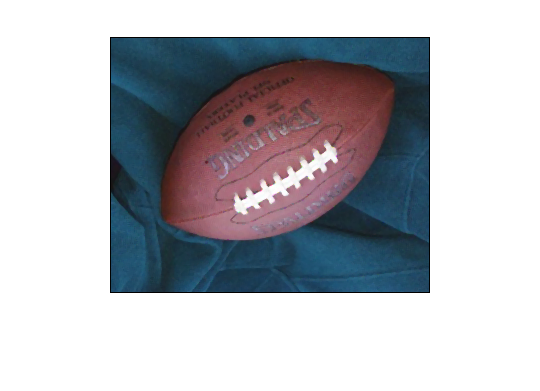

filtered_3 = uint8(filter(rotated, 3));
imshow(filtered_3)

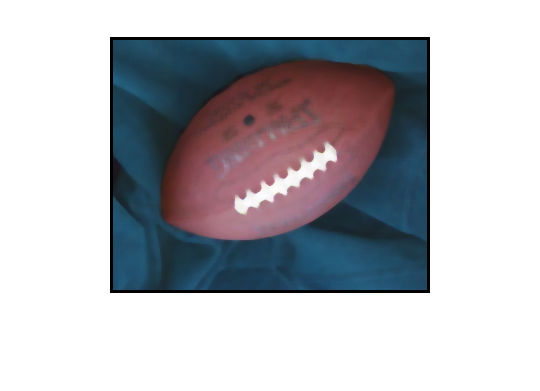

filtered_7 = uint8(filter(rotated, 7));
imshow(filtered_7)

- Increasing the kernel size increases the blurriness of the image. In this case, a kernel size of 3x3 is ideal.

## Manual Grayscaling

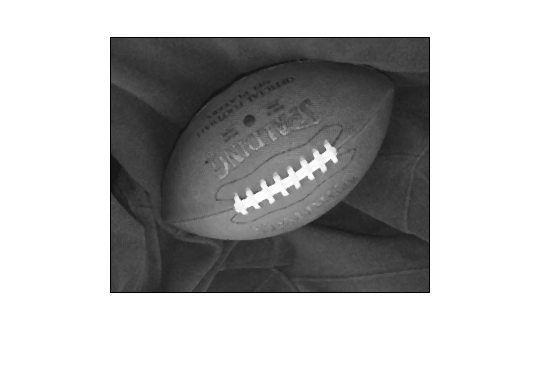

grayed_3 = uint8(rgb_to_gray(filtered_3));
imshow(grayed_3)

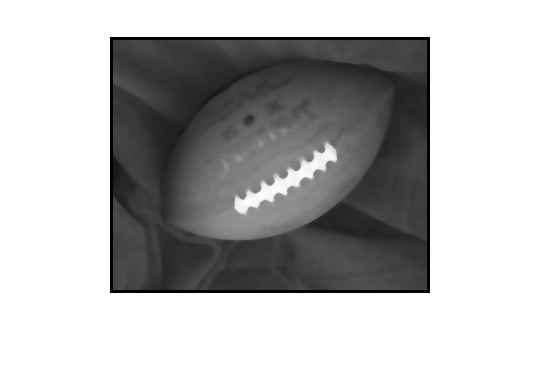

grayed_7 = uint8(rgb_to_gray(filtered_7));
imshow(grayed_7)

- The grayscaled version of the 3x3-filtered image produces better output because it exposes finer details/edges in the image that appear to be blurry and hazy in the 7x7-filtered one.

# External Functions

function out = rgb_to_gray(img)

out = ones(size(img, 1), size(img, 2));

for i = 1:size(img, 1)
    for j = 1:size(img, 2)
        out(i, j) = 0.3*img(i, j, 1) + 0.59*img(i, j, 2) + 0.11*img(i, j, 3);
    end
end

end

function out = filter(img, kernel_size)
% faster convolution can be done using convn()

inc = floor(kernel_size/2);

[x, y, z] = size(img);
out = ones(x, y, z);

bound_1 = floor(1 + inc);
bound_2 = floor(x - inc);
bound_3 = floor(y - inc);
for c = 1:z
    for i = bound_1:bound_2
        for j = bound_1:bound_3
            kernel = img(i-inc:i+inc, j-inc:j+inc, c);
            out(i, j, c) = median(kernel(:));
        end
    end
end

end

function out = rotate(A)

out = ones(size(A,1), size(A,2));

for c = 1:3
    for i = 1:size(A,1)
        for j = 1:size(A,2)
            out(size(A,1)-i+1, size(A,2)-j+1, c) = A(i, j, c);
        end
    end
end

end